unzip('kitchen.zip');
imds = imageDatastore('kitchen','IncludeSubfolders',true,'LabelSource','foldernames');
tbl = countEachLabel(imds)

tbl = 5×2 table
    Label     Count
    ______    _____

    Cap         5  
    Knife       5  
    Peeler      5  
    Spoon       5  
    mug         5  


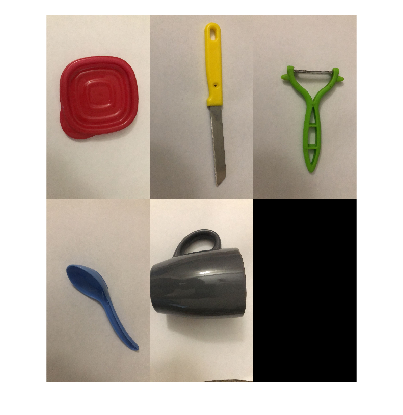

figure
montage(imds.Files(1:6:end))

[trainingSet, validationSet] = splitEachLabel(imds, 0.6, 'randomize');
bag = bagOfFeatures(trainingSet);

Creating Bag-Of-Features.
-------------------------
* Image category 1: Cap
* Image category 2: Knife
* Image category 3: Peeler
* Image category 4: Spoon
* Image category 5: mug
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 15 images...done. Extracted 2211840 features.

* Keeping 80 percent of the strongest features from each category.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 1769470
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 27/100 iterations (~3.57 seconds/iteration)...converged in 27 iterations.

* Finished creating Bag-Of-Features



img = readimage(imds, 1);
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


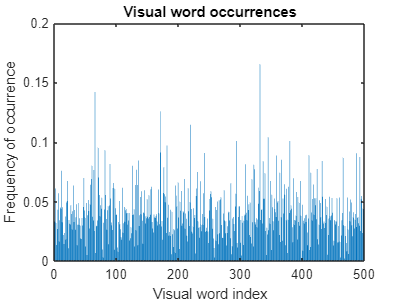

% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);

Error using toolboxdir (line 54)
Could not locate the base directory for stats.

Error in vision.internal.requiresStatisticsToolbox (line 7)
if ~isfolder(toolboxdir('stats'))

Error in 

confMatrix = evaluate(categoryClassifier, trainingSet);
confMatrix = evaluate(categoryClassifier, validationSet);
% Compute average accuracy
mean(diag(confMatrix))

img = imread(fullfile('kitchen','Knife','knife.jpeg'));
figure
imshow(img)
[labelIdx, scores] = predict(categoryClassifier, img);

% Display the string label
categoryClassifier.Labels(labelIdx)